watershedSegmentationTest_oversegmentation

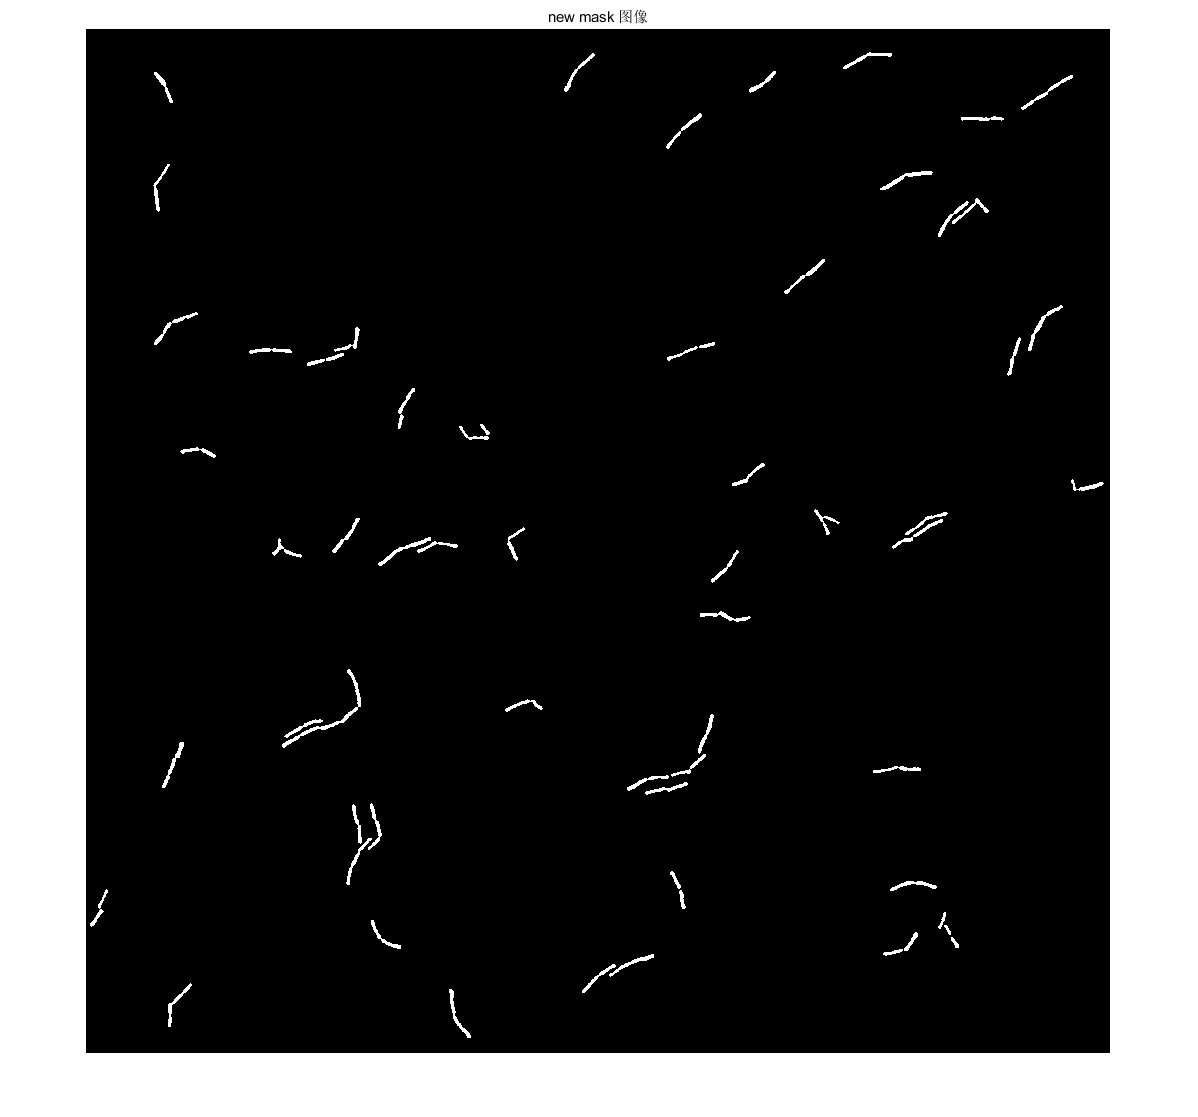

% oversegmentation
% image=import_tiff_stack('E:\2019-12-26 PAO1_deltpslpelfliC_IP32_100x ys\field0004\BF\imageBF04000.tif');


% [bw,~]=myImageProcessing_cBFys(I_eq,'w');
% imshow(bw)

I=false(2048,2048);
stats = regionprops(bw,'Centroid','MajorAxisLength','MinorAxisLength','PixelIdxList','PixelList');
for i=1:numel(stats)
    if numel(stats(i).PixelIdxList)>=500
        I(stats(i).PixelIdxList  )=1;
    end
end
imshow(I),title('new mask 图像')

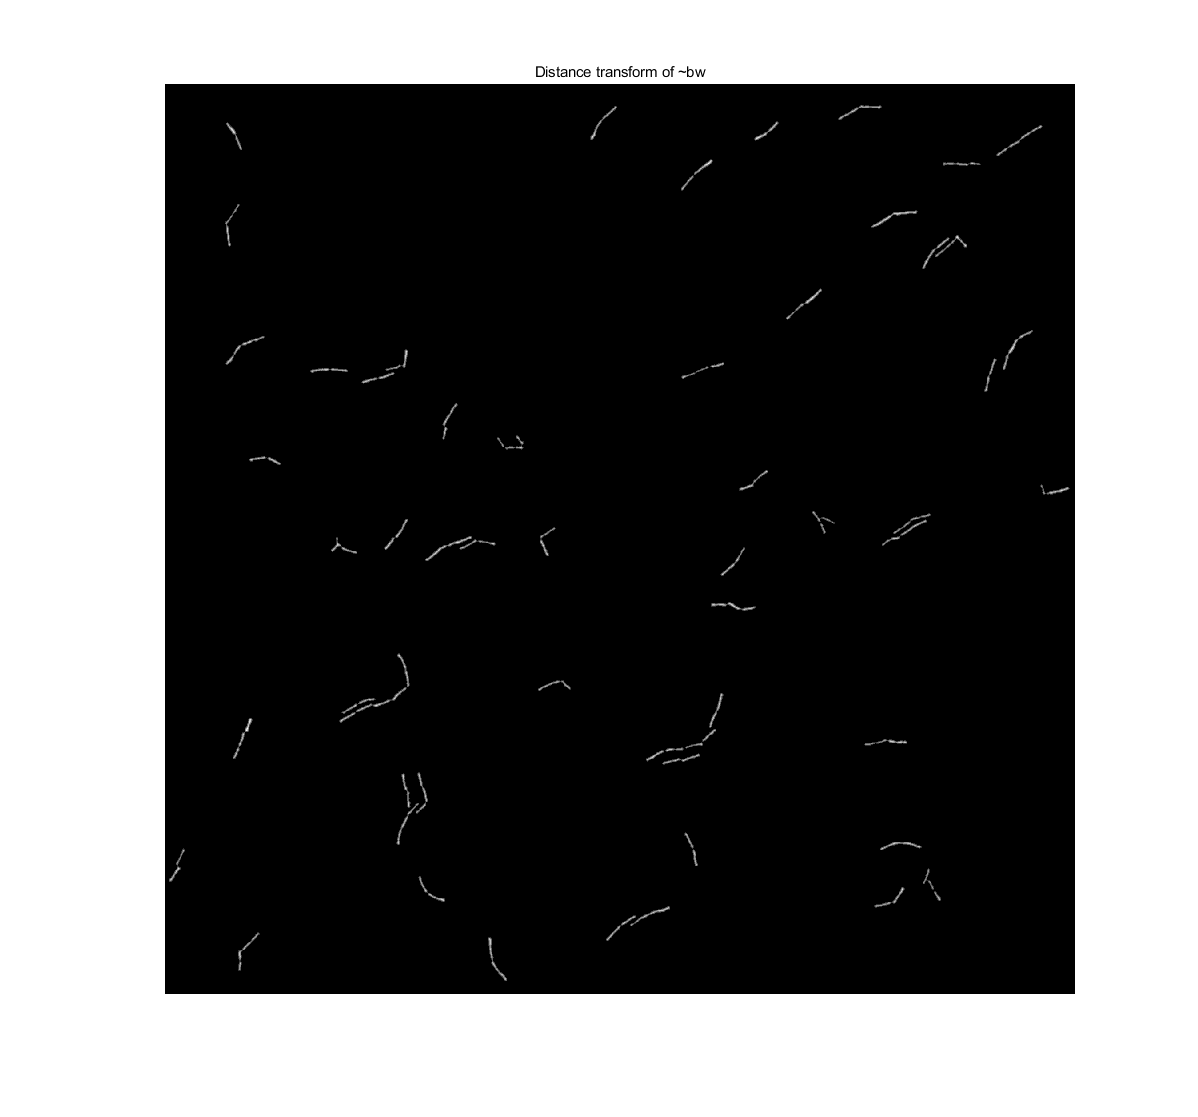


D = bwdist(~I);
imshow(D,[],'InitialMagnification','fit')
title('Distance transform of ~bw')

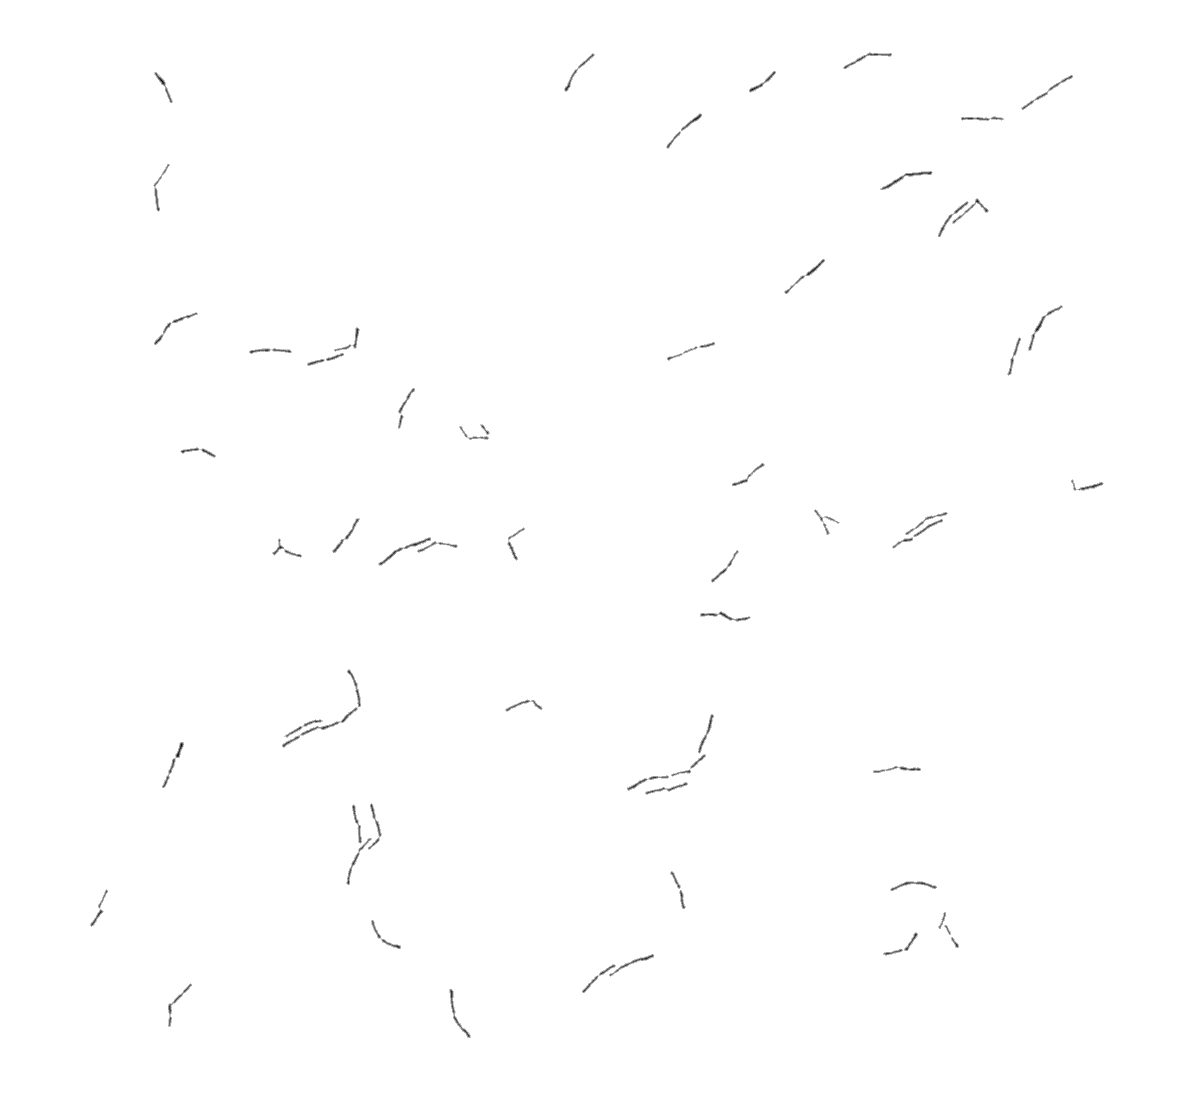


D = -D;
imshow(D,[]),title(' -D')

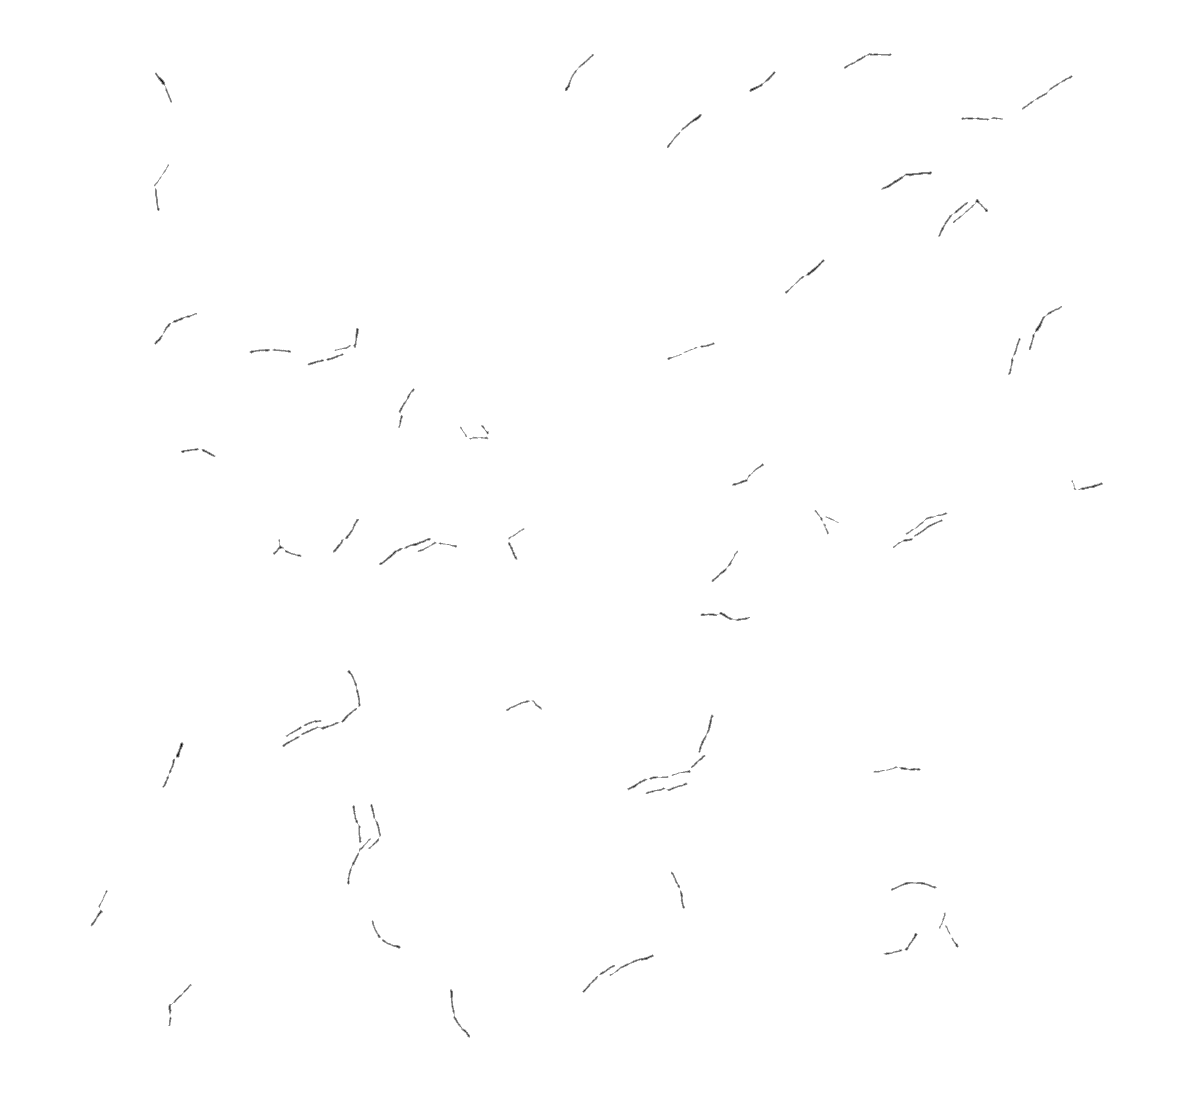

D(~I) = Inf;
imshow(D,[])

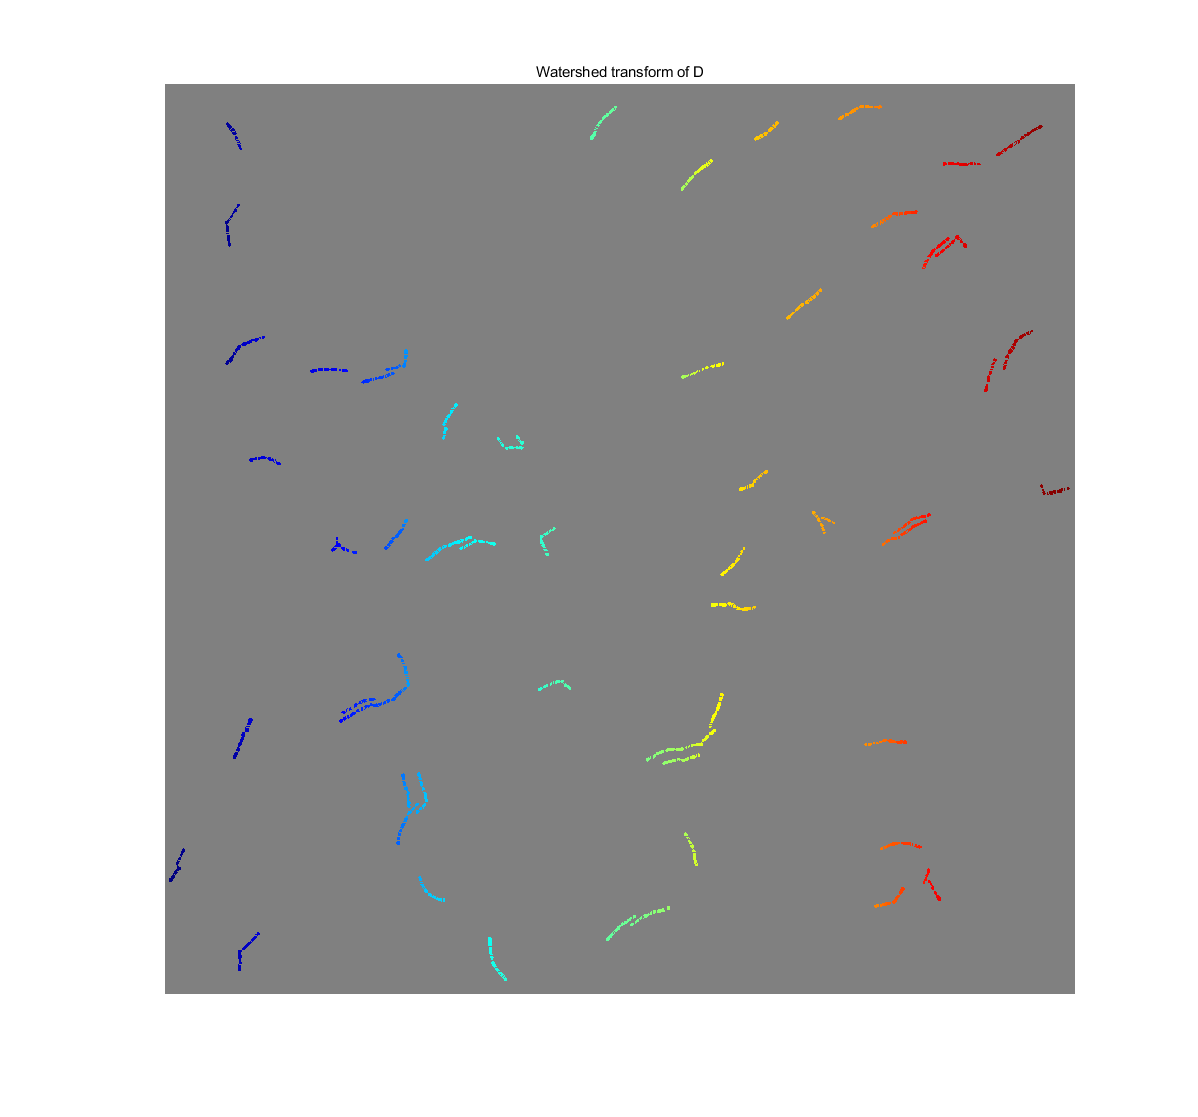


L = watershed(D);
L(~I) = 0;
rgb = label2rgb(L,'jet',[.5 .5 .5]);
imshow(rgb,'InitialMagnification','fit')
title('Watershed transform of D')

% oversegmentation